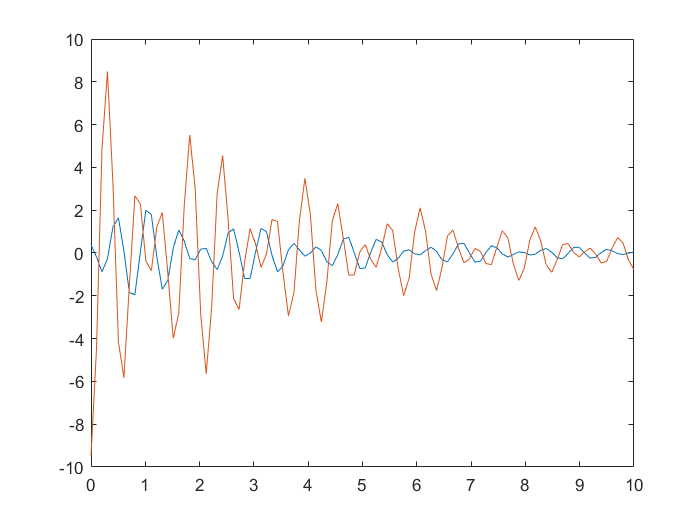

g =100;
L1 =1;
L2 =1;
m1 =10;
m2 =1;
c = 1;
A = [0,0,1,0;
    0,0,0,1;
    -g/(L1*m1)*(m1+m2),g*m2/(L1*m1),-c,0;
    g*(m1+m2)/(L2*m1),-g*(m1+m2)/(L2*m1),0,0];

U0 = [pi/8,0,0,0]';

T = 10;
N = 100;
h = T/(N-1);
t = 0:h:T;

U = zeros(4,N);
Y = zeros(4,4,N);
I = eye(4);
Ba = diag([1,0,1,1]);
Bb = diag([0,1,0,0]);
Betta = [pi/8,-pi/4,0,0]';

    alpha = [1,1,1,1]';
    for i = 1:N
        Y(:,:,i) = expm(A*t(i))*I;
        U(:,i) = expm(A*t(i))*alpha;
    end
    Q = Ba + Bb*Y(:,:,end);
    Betta_head = Betta - Ba*U(:,1) - Bb*U(:,end);
    s = Q\Betta_head;
    U0 = s + alpha;
    for i = 1:N
        U(:,i) = expm(A*t(i))*U0;
    end

plot(t,U(1,:))
hold on
plot(t,U(2,:))
hold off

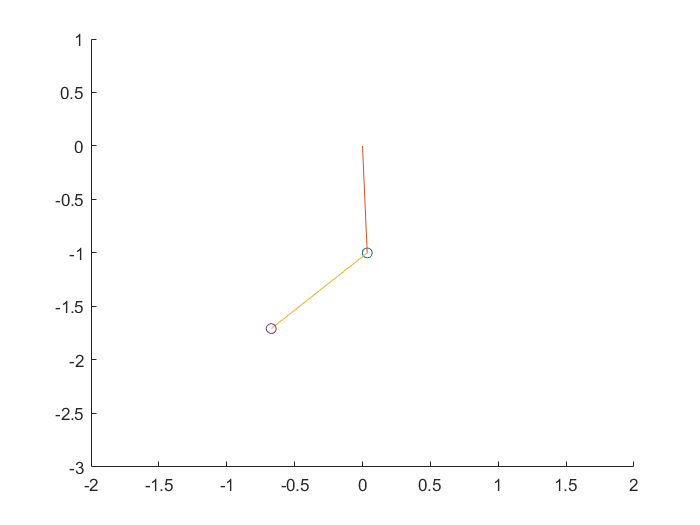

for i = 1:size(U,2)
    phi1 =U(1,i);
    phi2 =U(2,i);
    A1 = [sin(phi1)*L1,-cos(phi1)*L1];
    A2 = A1+[sin(phi2)*L2,-cos(phi2)*L2];
    scatter(A1(1),A1(2));
    hold on
    plot([0,A1(1)],[0,A1(2)])
    plot([A2(1),A1(1)],[A2(2),A1(2)])
    scatter(A2(1),A2(2));
    xlim([-2,2])
    ylim([-3,1])
    hold off
    pause(0.02);
end

i =1

i = 1

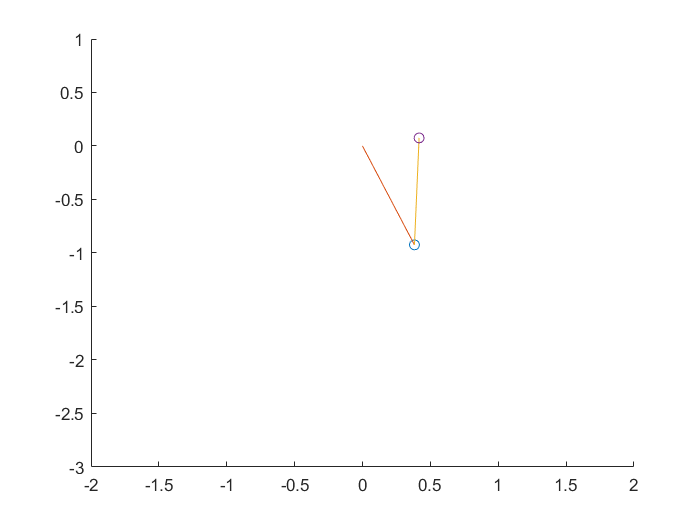

phi1 =U(1,i);
phi2 =U(2,i);
A1 = [sin(phi1)*L1,-cos(phi1)*L1];
A2 = A1+[sin(phi2)*L2,-cos(phi2)*L2];
scatter(A1(1),A1(2));
hold on
plot([0,A1(1)],[0,A1(2)])
plot([A2(1),A1(1)],[A2(2),A1(2)])
scatter(A2(1),A2(2));
xlim([-2,2])
ylim([-3,1])
hold off

i = N

i = 100

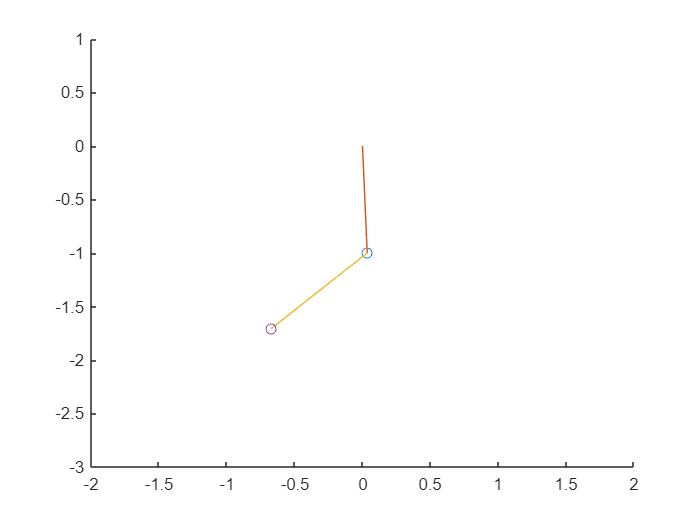

phi1 =U(1,i);
phi2 =U(2,i);
A1 = [sin(phi1)*L1,-cos(phi1)*L1];
A2 = A1+[sin(phi2)*L2,-cos(phi2)*L2];
scatter(A1(1),A1(2));
hold on
plot([0,A1(1)],[0,A1(2)])
plot([A2(1),A1(1)],[A2(2),A1(2)])
scatter(A2(1),A2(2));
xlim([-2,2])
ylim([-3,1])
hold off